% UoM_RS_Starter_Code.mlx
% --------------------------
% Licenting Information: You are free to use or extend this project
% for educational purposes provided that (1) you do not distribute or
% publish solutions, (2) you retain this notice, and (3) you provide 
% clear attribution to the University of Melbourne, Department of 
% Mechanical Engineering and Product Design Lab.
% 
% Attribution Information: The ChessBot project was developed in collaboration
% between Product Design Lab & the University of Melbourne. The core project was 
% primarily developed by Professor Denny Oetomo (doetomo@unimelb.edu.au). All 
% Starter Code and libraries were developed by Nathan Batham of Product
% Design Lab
% (nathan@productdesignlab.com.au)

## Add Files to Path

% Clear workspace variables
clear   

% Set the location of this file as the current folder
cd(fileparts(matlab.desktop.editor.getActiveFilename)); 

% Add the library folter to path
addpath("UoM_RS_MATLAB_Libraries")  

load("UoM_RS_MATLAB_Libraries/UoM-RS-Var_Def.mat"); % Load default variables into the workspace

Error using load
Unable to find file or directory 'UoM_RS_MATLAB_Libraries/UoM-RS-Var_Def.mat'.


% Set the port connected to the Arduino
%port = '/dev/cu.usbmodem1101';          % MacOS Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS
port = 'COM7';                        % Windows Port Structure - ONLY EXAMPLE, MAY NOT BE EXACT ADDRESS

## Create Robot & Connect To Arduino

% Create Robot Object
my_robot = robot(port,MAX_ID,BAUDRATE);

% Connect to Arduino
my_robot.ConnectToArduino();

% Get & Display Connected Motor IDs
my_robot.getID();
my_robot.num_ID
my_robot.connected_ID


## Set Control Mode For Each Motor

% Define whether each motor should be in velocity of position mode
motor_control = [POSITION POSITION POSITION POSITION POSITION VELOCITY];

%motor_control = [VELOCITY VELOCITY VELOCITY VELOCITY VELOCITY VELOCITY];

% Update motor control mode
my_robot.setDriveControlMode(motor_control);



## Read Feedback - EXAMPLE

% Read motor feedback
my_robot.getFB();

% Display motor feedback
my_robot.q_FB


## Drive Motors - EXAMPLE

% Set position or velocity variables
% Note: the indexes should line up with your motor_control variable
% i.e., if ID 1 is set to Velocity, its value should be put in setQDot
my_robot.setQ([pi/2 0 0 0 0 0]);
my_robot.setQDot([0 0 0 0 0 0]);
my_robot.driveMotors();

## Main Loop - EXAMPLE

figure;
hold on;
for i=1:500

    % Set position or velocity variables

    if i < 100
        my_robot.setQ([0 0 pi*sin(i*pi/250)+pi pi*sin(i*pi/250)+pi pi*sin(i*pi/150)+pi 0]);
        my_robot.setQDot([deg2rad(50) 0 0 0 0 pi*sin(i*pi/150)]);
    else
        my_robot.setQ([pi pi/2 pi*sin(i*pi/250)+pi pi*sin(i*pi/250)+pi pi*sin(i*pi/150)+pi 0]);
    my_robot.setQDot([deg2rad(50) 0 0 0 0 pi*sin(i*pi/150)]);

    end
    

    % Send values to Motor
    my_robot.driveMotors();

    % Get (but don't display) motor feedback
    fb = my_robot.getFB();
 
    subplot(2, 2, 1)
    plot(i, rad2deg(fb.q_FB(1)), "o", 'Color', "r")
    hold on
    subplot(2, 2, 2)
    plot(i, rad2deg(fb.q_FB(2)), "o", 'Color', "r")
    hold on

    if i < 100
        subplot(2, 2, 3)
        plot(i, 0 - rad2deg(fb.q_FB(1)), "o", 'Color', "r")
        hold on

        subplot(2, 2, 4)
        plot(i, 0 - rad2deg(fb.q_FB(2)), "o", 'Color', "r")
        hold on
    else
        subplot(2, 2, 3)
        plot(i, 180 - rad2deg(fb.q_FB(1)), "o", 'Color', "r")
        hold on;

        subplot(2, 2, 4)
        plot(i, 90 - rad2deg(fb.q_FB(2)), "o", 'Color', "r")
        hold on;

    end




end

% Ensure all velocity controlled motors are set to zero
my_robot.setQDot([0 0 0 0 0 0]);
my_robot.driveMotors();



## Main Loop - Play Game

% init variables
close all
clear all
clc

% who decides each move? 0 = predefined game, 1 = robot, 2 = human
ThinksWhite = 0;
ThinksBlack = 0;

% Does the robot move the pieces? 0 = no, 1 = yes
RobotMovesWhite = 1;
RobotMovesBlack = 0;

% White starts: 0 = white's move, 1 = black's move
turn = 0;

% Keep track of the number of moves
numMoves = 0;

% Keep track of whether game is active
gameState = 0;

% Thinking time for Stockfish
thinkingTime = 0.1;

if ThinksWhite == 0 || ThinksBlack == 0
    moves = MoveSequence();
end



% Return to home position before game starts

% Construct game and engine objects
CM = ChessMaster();

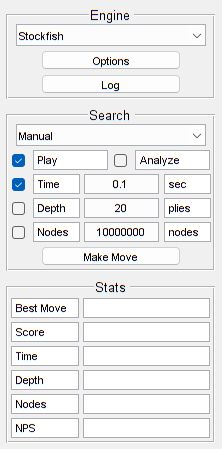

CE = ChessEngine(CM,CM.engines,'ChessEngine',[300 300]);

% Update engine search time
CE.ChangeSearchTime(thinkingTime)

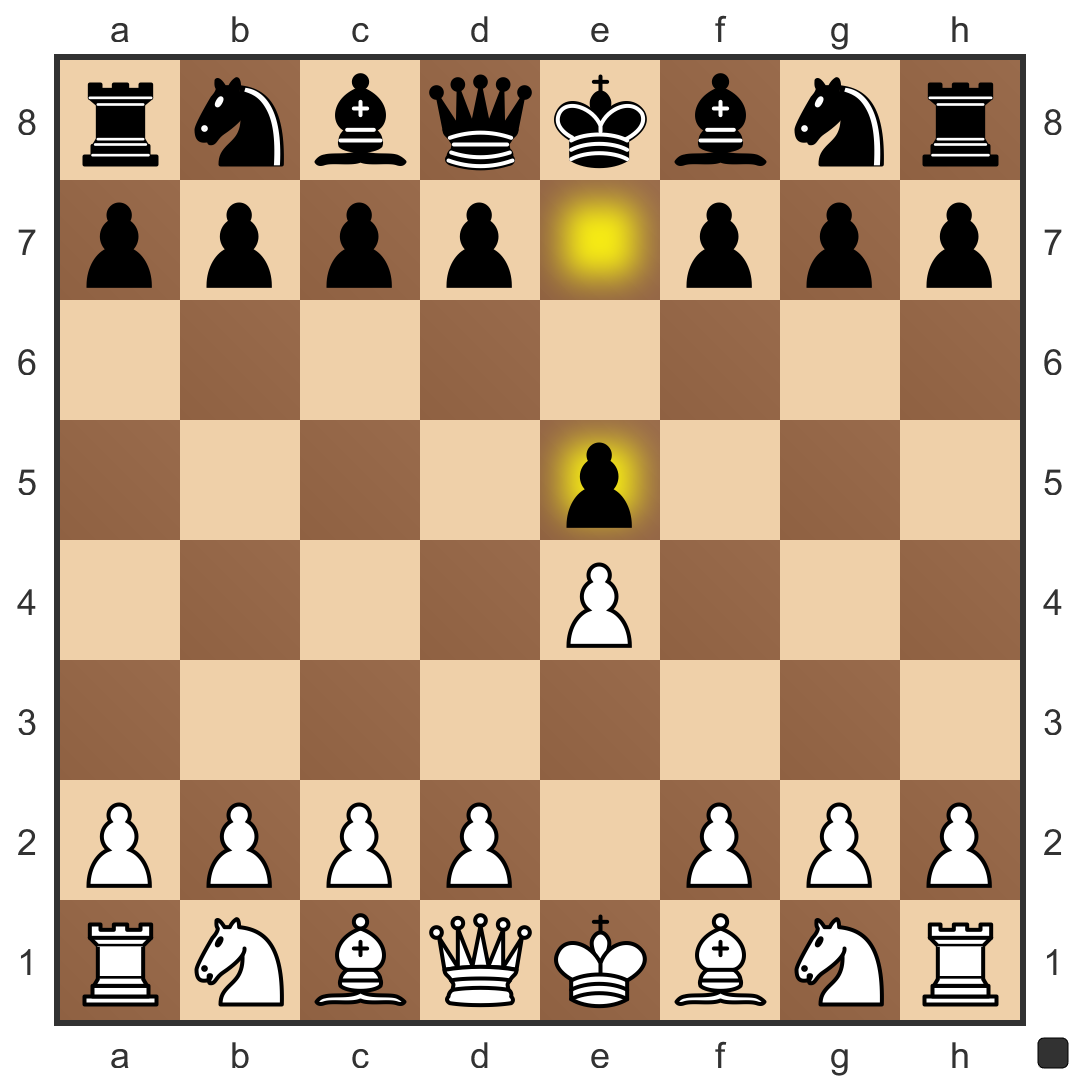

Move from game:


e2e4


prevBoard = 8×8 char array
    'RNBQKBNR'
    'PPPPPPPP'
    'eeeeeeee'
    'eeeeeeee'
    'eeeeeeee'
    'eeeeeeee'
    'pppppppp'
    'rnbqkbnr'


currentBoard = 8×8 char array
    'RNBQKBNR'
    'PPPPePPP'
    'eeeeeeee'
    'eeeePeee'
    'eeeeeeee'
    'eeeeeeee'
    'pppppppp'
    'rnbqkbnr'


char
e
   101



startpos =      2     5


endpos =      4     5


Move from game:


e7e5




%% Main Loop %%
while gameState == 0
    clear move
    prevFen = CM.GetFENstr();

    if turn == 0
        switchCase = ThinksWhite;
        
    else
        switchCase = ThinksBlack;

    end


    switch switchCase
        case 0
            %input("Press any key for next move", "s")
            % Take move from moves array
            move = moves(floor(numMoves/2) + 1, mod(numMoves,2) + 1);
            move = convertStringsToChars(move);
            CM.MakeMove(move);

            disp('Move from game:')
            disp(move)
        case 1
            % Generate move via stockfish
            CE.MakeMove();
            pause(thinkingTime + 0.1);
            % Get move
            temp = CM.GetLANstrs();
            move = string(temp(end));
            move = convertStringsToChars(move);
            % Print last move
            disp('The robot moved:')
            disp(move);
        case 2
            % Enter command and check if legal
            isLegal = 0;
            while isLegal == 0
                move = input("What is your move?\n","s");
                if move == 'exit'
                    gameState = 1;
                    break;
                elseif strcmp(MakeMove(CM,move),'') == 0

                    isLegal = 1;
                else
                    disp("Illegal Move")
                end
            end
            CM.MakeMove(move);
    end

    if gameState == 1
        % Return robot to home position
        break
    end

    %MoveSequence = genMoveSequence(CM, move, prevFen)

    if (turn == 0 && RobotMovesWhite == 1) || (turn == 1 && RobotMovesBlack == 1)
        % send command to figure out move sequence including pincer gripping, including returning to home pose
        MoveSequence = genMoveSequence(CM, move, prevFen);

        % generate trajectories

        % Send trajectories to robot via control loop

        % Wait until robot is back in home position
    else
        prompt = "Press enter to continue after manually moving " + convertCharsToStrings(move) + "..."; 
        input(prompt, "s")
    end

    turn = ~turn;
    numMoves = numMoves + 1;

    % Check for end of game
    if CM.isGameOver == true
        gameState = 1;
    end
end


disp("Game finished!")

  


## Close Serial Connection

% Disconnect the serial port - required to upload Arduino code
delete(my_robot.serial_obj);